# Elaborato equazioni differenziali - combustione

Dato il modello di combustione di un combustibile:


$$\begin{array}{l}
\mathrm{y'}\left(t\right)=y^2 \left(t\right)-y^3 \left(t\right),t\in \left\lbrack 0,\frac{2}{d}\right\rbrack \\
y\left(0\right)=d
\end{array}$$


dove y(t) rappresenta il raggio e d il raggio iniziale.

Si vuole risolvere il sistema con $d=0\ldotp 01,d=0\ldotp 0001,d=0\ldotp 00001$con ode45 e ode15s con `RelTol=10e-4 `e fare il grafico della soluzione e determinare il numero di punti utilizzato. Cosa si osserva?

# Soluzione

Saranno confrontati i risultati ottenuti con le due funzioni per i diversi valori di *d* e, per ciascuno di essi, sarà mostrato il numero di punti analizzati. A tale proposito, è stata utilizzata la funzione `ode_comparation.m`, allegata alla documentazione, che fornisce anche i risultati ottenuti dalle due funzioni della ode suite eseguite, che potrebbero essere utili per successive analisi.

[d = 1.000000e-02], [ODE45], Numero di punti: 157
[d = 1.000000e-02], [ODE15s], Numero di punti: 50


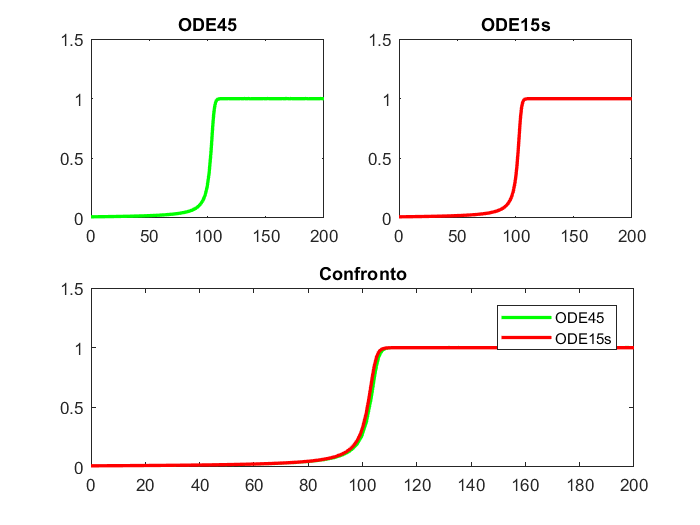

[res45_01, res15s_01] = ode_comparation(0.01);

[d = 1.000000e-04], [ODE45], Numero di punti: 12113
[d = 1.000000e-04], [ODE15s], Numero di punti: 108


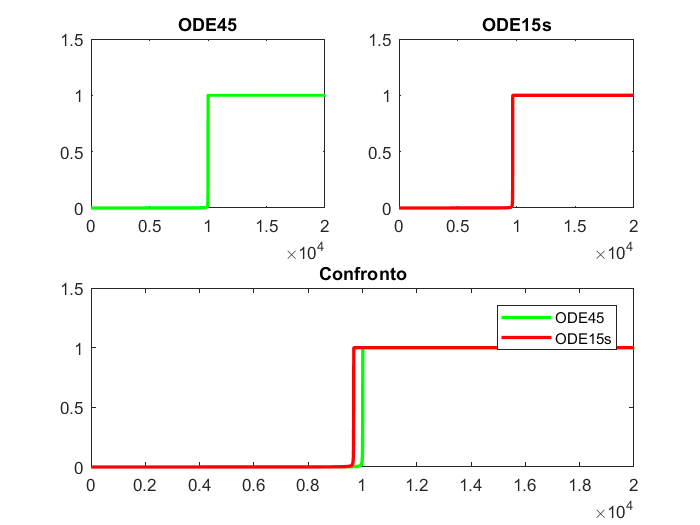

[res45_0001, res15s_0001] = ode_comparation(0.0001);

[d = 1.000000e-05], [ODE45], Numero di punti: 120565
[d = 1.000000e-05], [ODE15s], Numero di punti: 98


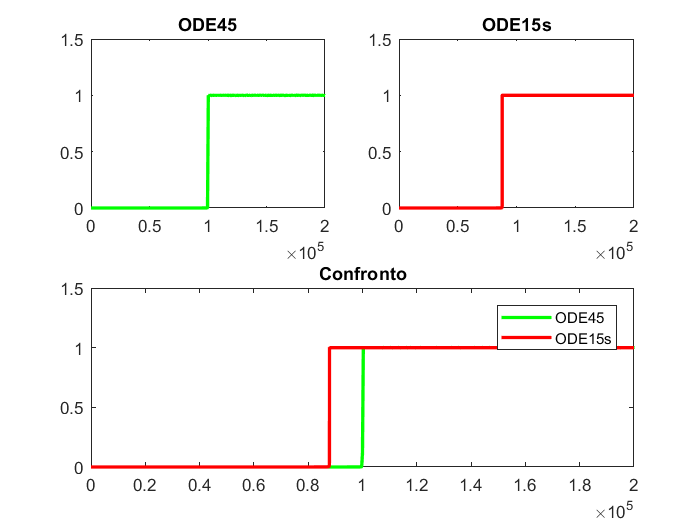

[res45_00001, res15s_00001] = ode_comparation(0.00001);

Si può facilmente osservare che sia ode45 che ode15s riescono a calcolare la soluzione, ma confrontando i risultati in termini di numero di punti utilizzati, è immediato rendersi conto che il modello di combustione, al diminuire del raggio iniziale, diventa un problema di tipo *stiff, *risultando un problema difficile per ode45 e facile per ode15s. 

d_values = {'d=0.01', 'd=0.0001', 'd=0.00001'};
ODE45_points = [length(res45_01.y) length(res45_0001.y) length(res45_00001.y)]';
ODE15s_points = [length(res15s_01.y) length(res15s_0001.y) length(res15s_00001.y)]';

T = table(ODE45_points,ODE15s_points,'RowNames',d_values)

T = 3×2 table
                 ODE45_points    ODE15s_points
                 ____________    _____________

    d=0.01              157       50          
    d=0.0001          12113      108          
    d=0.00001    1.2057e+05       98          


A titolo didattico si riporta anche una giustificazione teorica per cui il problema è stiff: lo jacobiano associato alla funzione termine noto è molto grande per cui la scelta del passo incrementale h non può essere eseguita con metodi ordinari.

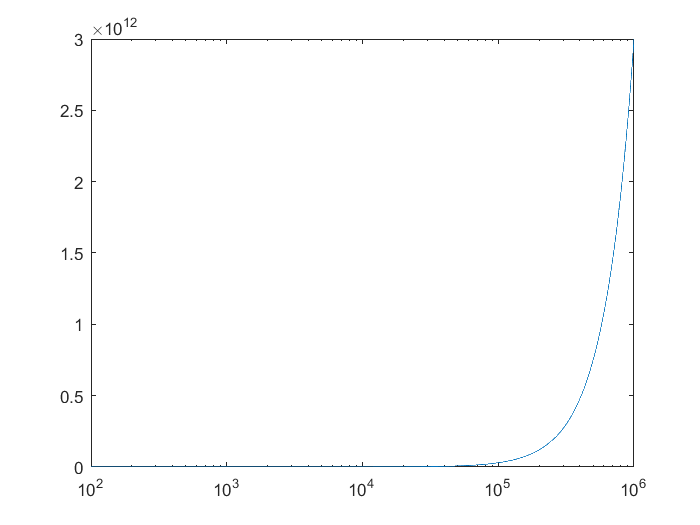

t = 1e2:1:1e6;
f = t.^2-t.^3;  % è la f che compare nell'espressione dell'eq. differenziale
J=[0 diff(f,1)];    % lo jacobiano è scalare dato che il problema è del primo ordine

figure();
semilogx(t,abs(J),'-');